# EECE 5644 Intro to Machine Learning Homework #1

## Problem 1.1

Let *x * be a real-valued random variable

**(a.) **Prove that the variance of $x=\sigma^2 =E\left\lbrack {\left(x-\mu \right)}^2 \right\rbrack =E\left\lbrack x^2 \right\rbrack -\mu^2$

To start we expand the the inner expression into polynomial form


$$x=\sigma^2 =E\left\lbrack \left(x-\mu \right)\left(x-\mu \right)\right\rbrack =E\left\lbrack x^2 -x\mu -x\mu +\mu^2 \right\rbrack =E\left\lbrack x^2 -2x\mu +\mu^2 \right\rbrack$$


Then, using the Mean properties of Moments $\left(E\left\lbrack x\right\rbrack =\mu \right)$, this inner expression becomes


$$x=\sigma^2 =E\left\lbrack x^2 \right\rbrack -2E\left\lbrack x\right\rbrack \mu +E\left\lbrack \mu^2 \right\rbrack =E\left\lbrack x^2 \right\rbrack -2\mu \mu +E\left\lbrack E{\left\lbrack x\right\rbrack }^2 \right\rbrack$$


This can then be simplified into


$$x=\sigma^2 =E\left\lbrack x^2 \right\rbrack -2\mu^2 +\mu^2$$



$$x=\sigma^2 =E\left\lbrack x^2 \right\rbrack -\mu^2$$


Thus, the definition of the variance can be expressed in this form.

**(b.) **Let **x ** be a real-valued random vector. Prove that the covariance matrix of $x=\Sigma =E\left\lbrack {\textrm{xx}}^T \right\rbrack -\mu \mu^T$

Again, we start by expanding the inner products to form a polynomial


$$\Sigma =E\left\lbrack {\left(x-\mu \right)}^T \right\rbrack =E\left\lbrack \left(x-\mu \right){\left(x-\mu \right)}^T \right\rbrack =E\left\lbrack {\textrm{xx}}^T -x\mu^T -\mu x^T +\mu \mu^T \right\rbrack$$


Using the Mean property of Moments, $E\left\lbrack x\right\rbrack =\mu$ in this vector form yields:


$$\Sigma =E\left\lbrack {\textrm{xx}}^T \right\rbrack -E\left\lbrack x\mu^T +\mu x^T \right\rbrack +\mu \mu^T =E\left\lbrack {\textrm{xx}}^T \right\rbrack -E\left\lbrack x\right\rbrack \mu^T -\mu E\left\lbrack x^T \right\rbrack +\mu \mu^T$$



$$\Sigma =E\left\lbrack {\textrm{xx}}^T \right\rbrack -\mu \mu^T -\mu \mu^T +\mu \mu^T =E\left\lbrack {\textrm{xx}}^T \right\rbrack -2\mu \mu^T +\mu \mu^T$$



$$\Sigma =E\left\lbrack {\textrm{xx}}^T \right\rbrack -\mu \mu^T$$


Thus, the covariance matrix of $x=\Sigma =E\left\lbrack {\textrm{xx}}^T \right\rbrack -\mu \mu^T$

## Problem 1.2

Suppose two equally probable one-dimensional densities are of the form$p\left(x\left|\omega_i \right.\right)\proptoe^{-\left|x-a_i \right|/b_i }$ for $i=1,2$ and $b>0$

**(a.) **Write an analytic expression for each density, that is, normalize each function for arbitrary $a_i$, and positive$\;b_i$. 

We start with the fact that $\int_{-\infty}^{\infty}p(x|\omega_i)dx = 1$, and because we are dealing with two equally probable densities, they must also sum to one. Writing them both out gives


$$A\left[\int_{-\infty}^{a_i} e^{\frac{|x-a_i|}{b_i}} dx+ \int_{a_i}^{\infty} e^{-\frac{|x-a_i|}{b_i}} dx\right] = 1$$
 

where, the factor $A$ should normalize each function, so we solve by find $2b_i A=1\to A=\frac{1}{2b_i }$ and now the normalization will be independent of $a_i$

Thus, our distribution can be written as $p\left(x\left|\omega_i \right.\right)=\frac{1}{2b_i }e^{-\frac{\left|x-a_i \right|}{b_i }}$

**(b.) **Calculate the likelihood ratio $p\left(x\left|\omega_1 \right.\right)/p\left(x\left|\omega_2 \right.\right)$ as a function of your four variables

Using the defined expression above we calculate the likelihood ratio to be:


$$\frac{p\left(x\left|\omega_1 \right.\right)}{p\left(x\left|\omega_2 \right.\right)}=$$
 
$$\frac{\frac{1}{2b_1}}{\frac{1}{2b_2}}\frac{e^{-\frac{|x-a_1|}{b_1}}}{e^{-\frac{|x-a_2|}{b_2}}} = \frac{b_2}{b_1} e^{-\frac{|x-a_1|}{b_1}}e^{\frac{|x-a_2|}{b_2}} = \frac{b_2}{b_1} e^{-\frac{|x-a_1|}{b_1}+{\frac{|x-a_2|}{b_2}}$$


**(c.) **Plot a graph of the likelihood ratio for the case of $a_1 =0,{\;b}_1 =1,{\;a}_2 =1,$ and $b_2 =2\ldotp$ Make sure the plots are correctly labeled (axis, titles, legend, etc) and that the fonts are legible when printed.

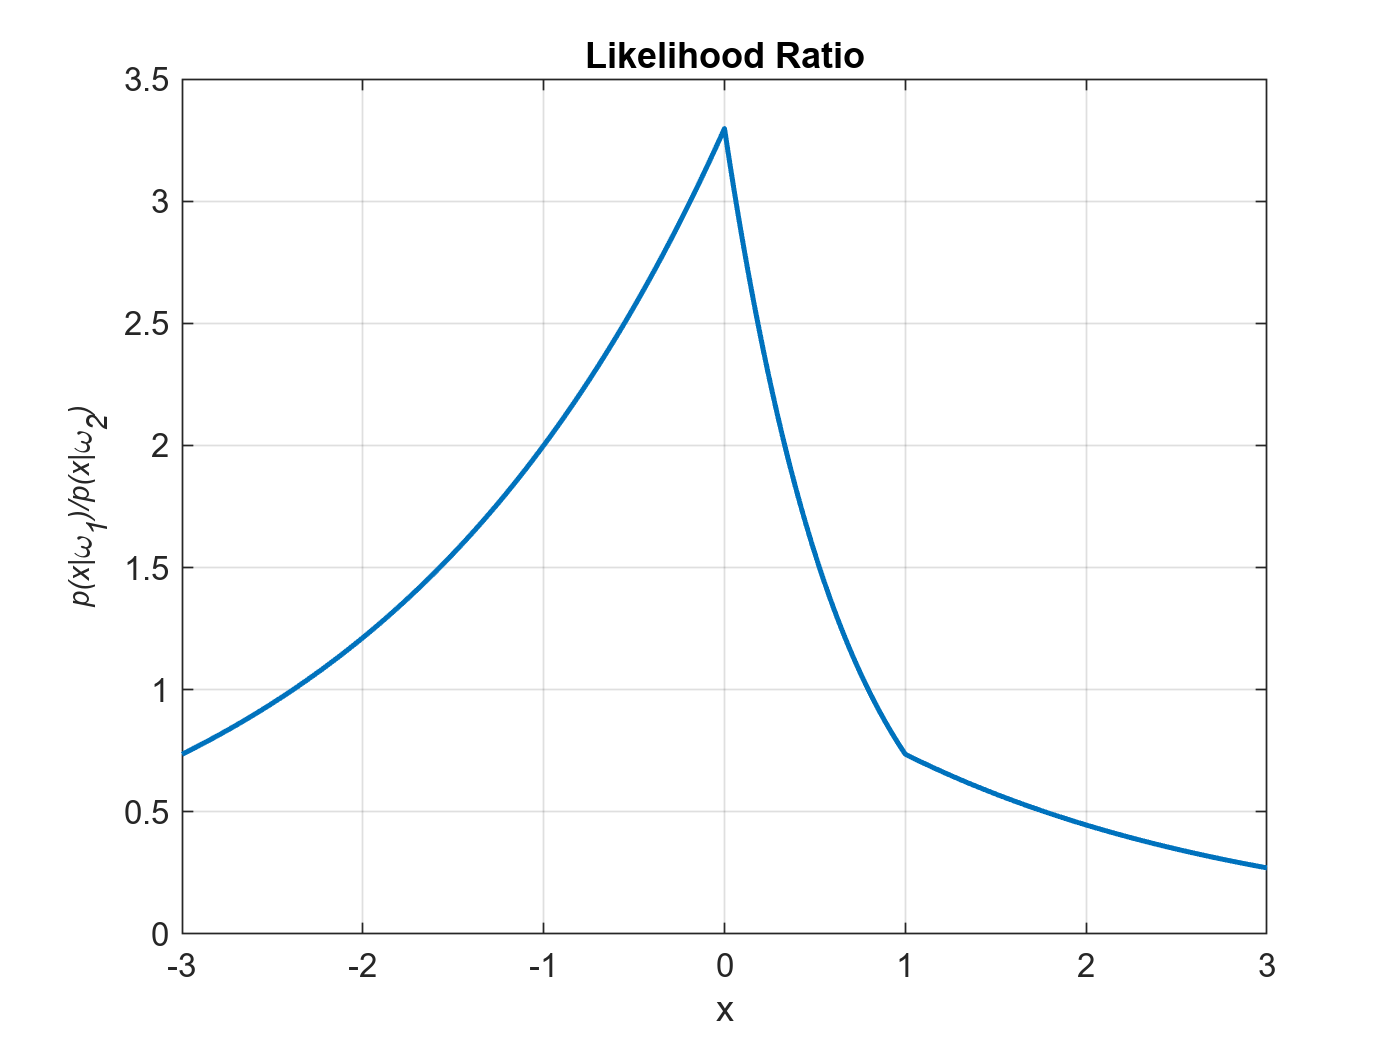

a1 = 0; b1 = 1; a2 = 1; b2 = 2;
x = -3:0.01:3;
likelihoodRatio = (b2/b1).*exp(-(abs(x-a1)./b1) + (abs(x-a2)./b2));
figure
plot(x,likelihoodRatio,'LineWidth',1.5), grid on, xlabel('\it{x}'), ylabel('\it{p(x|\omega_1)/p(x|\omega_2)}')
title('Likelihood Ratio')

## Problem 1.3

Consider a two-class problem, with classed $c_1$ and $c_2$ where $P\left(c_1 \right)=P\left(c_2 \right)=0\ldotp 5$. There is a one-dimensional feature variable $x$. Assume that the $x$ data for $c_1$ is uniformly distributed between $a$ and $b$, and the $x$ data for $c_2$ is uniformly distributed between $r$ and $t\ldotp$ Assume that $a<r<b<t$. Derive a general expression for the Bayes error rate for this problem. (Hint: a sketch may help you think about the solution.)

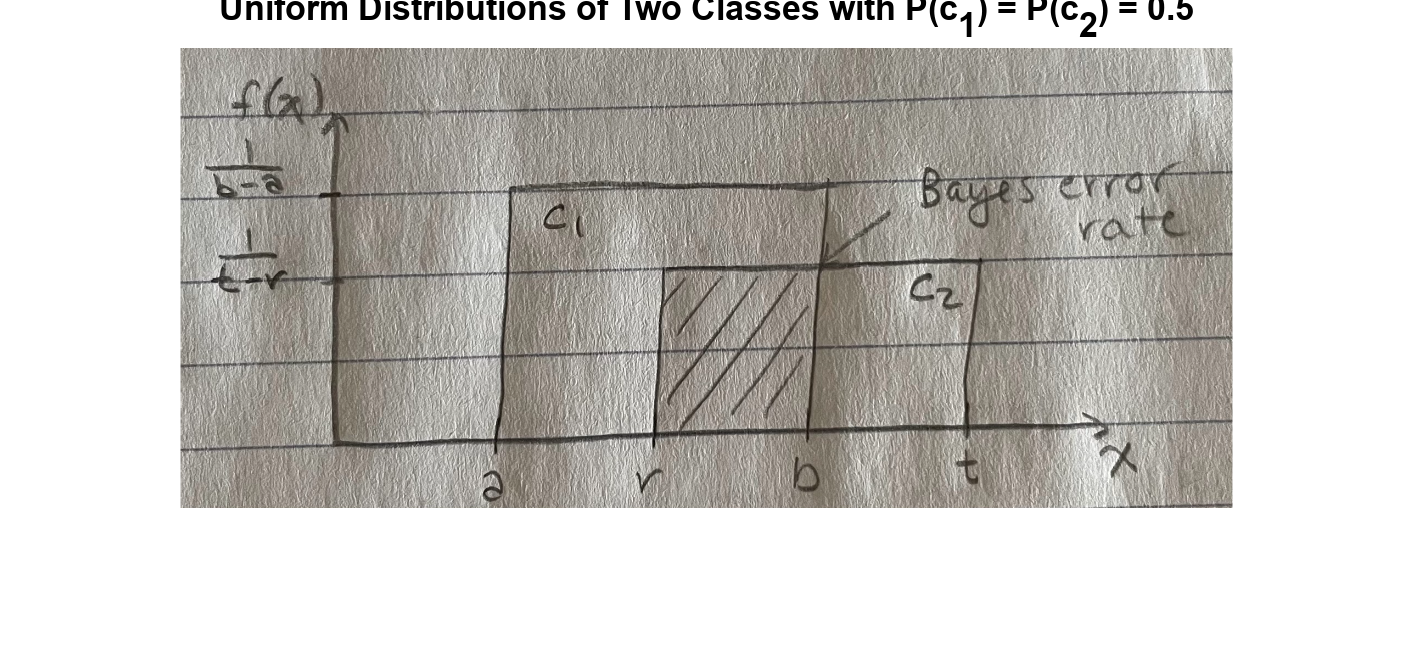

f = imread('ML_HW1_P3.png'); imshow(f);
title('Uniform Distributions of Two Classes with P(c_1) = P(c_2) = 0.5')

Here, we're making the assumption that the heights of these distributions are different so, $\frac{1}{b-a}>\frac{1}{t-r}$

Bayes Error Rate can be described as:


$$Bayes Error Rate = P(c_2|c_1)P(c_1) + P(c_1|c_2)P(c_2)$$


Since the conditional probabilities will have $P\left(c_1 \right)=P\left(c_2 \right)=0\ldotp 5$ in the denominator and we are multiplying by them in the numerator, these terms cancel, leaving:


$$Bayes Error Rate = P(c_2|c_1) + P(c_1|c_2)$$


Solving for each intersections gives:


$$Bayes Error Rate = (b-r)\left(\frac{1}{t-r}\right) + (b-r)\left(\frac{1}{t-r}\right)$$



$$Bayes Error Rate = 2\left(\frac{b-r}{t-r}\right)$$


## Problem 1.4

Consider a two-class, one-dimensional problem where $P\left(\omega_1 \right)=P\left(\omega_2 \right)$ and $p\left(x\left|\omega_i \right.\right)~N\left(\mu_i ,\sigma_i^2 \right)\ldotp$ Let $\mu_1 =0,\;\sigma_1^2 =1,{\;\mu }_2 =\mu ,$ and $\sigma_2^2 =\sigma^2 \ldotp$

**(a.) **Derive a general expression for the locations of the Bayes optimal decision boundary as a function of $\mu$ and $\sigma^2 \ldotp$

Since we know that the Prior values are equivalent, and there is no mention for a Cost, the decision for a boundary should come from the comparisons of the likelihoods. In general, we make the decision that if:

$p\left(x\left|\omega_1 \right.\right)P\left(\omega_1 \right)>p\left(x\left|\omega_2 \right.\right)P\left(\omega_2 \right)$ we decide $\omega_1$; else decide $\omega_2$

And since $P\left(\omega_1 \right)=P\left(\omega_2 \right)$, we can eliminate these terms on both sides and solve for a general expression in terms of $\mu$ and $\sigma^2$


$$\frac{1}{\sqrt{2\pi \sigma^2 }}e^{-\frac{1}{2}{{\left(\frac{x-\mu_1 }{\sigma^2 }\right)}^2 } } >\frac{1}{\sqrt{2\pi \sigma^2 }}e^{-\frac{1}{2}{{\left(\frac{x-\mu_2 }{\sigma^2 }\right)}^2 } }$$


multiplying each side by $\sqrt{2\pi \sigma^2 }$ results in:


$$e^{-\frac{1}{2}{{\left(\frac{x-\mu_1 }{\sigma^2 }\right)}^2 } } >e^{-\frac{1}{2}{{\left(\frac{x-\mu_2 }{\sigma^2 }\right)}^2 } }$$


Taking the natural log of both sides yields:


$$-\frac{{\left(x-\mu_1 \right)}^2 }{2\sigma^2 }>-\frac{{\left(x-\mu_2 \right)}^2 }{2\sigma^2 }\;$$


Multiplying by each side by $-2\sigma^2$ will flip the equality


$${\left(x-\mu_1 \right)}^2 <{\left(x-\mu_2 \right)}^2$$


Now unraveling these terms into polynomials gives us:


$$x^2 -2\mu_1 x+\mu_1^2 <x^2 -2\mu_2 x+\mu_2^2 \;$$


Subtracting the $x^2$ terms and moving the others to separate sides:


$$-2x\left(\mu_2 -\mu_1 \right)<\mu_2^2 -\mu_1^2$$


Simplifying even further results in the final expression to determine the boundary:


$$x<\frac{\left(\mu_2 -\mu_1 \right)}{2}$$


So, the decision boundary will be determined by the values of the means from the Gaussian distributions

**(b.) **With $\mu =1$ and $\sigma^2 =2,$ make two plots: 

- one for the class conditional pdfs $p\left(x\left|\omega_i \right.\right)$

- one for the posterior probabilities $p\left(\omega_i \left|x\right.\right)$ with the location of the optimal decision regions.

mu1 = 0; sigma1 = 1; 
mu2 = 1; sigma2 = 2;
x = -7:0.01:7; 
pxw1 = (1/sqrt(2*pi*sigma1)).*exp(-(1/2).*((x-mu1).^2)./sigma1);
pxw2 = (1/sqrt(2*pi*sigma2)).*exp(-(1/2).*((x-mu2).^2)./sigma2);
xquad = [(1-sigma2) -2*mu2 (mu2^2+2*sigma2*log(sqrt(sigma2)))];
x_roots = roots(xquad)

x_roots =    -2.8402
    0.8402


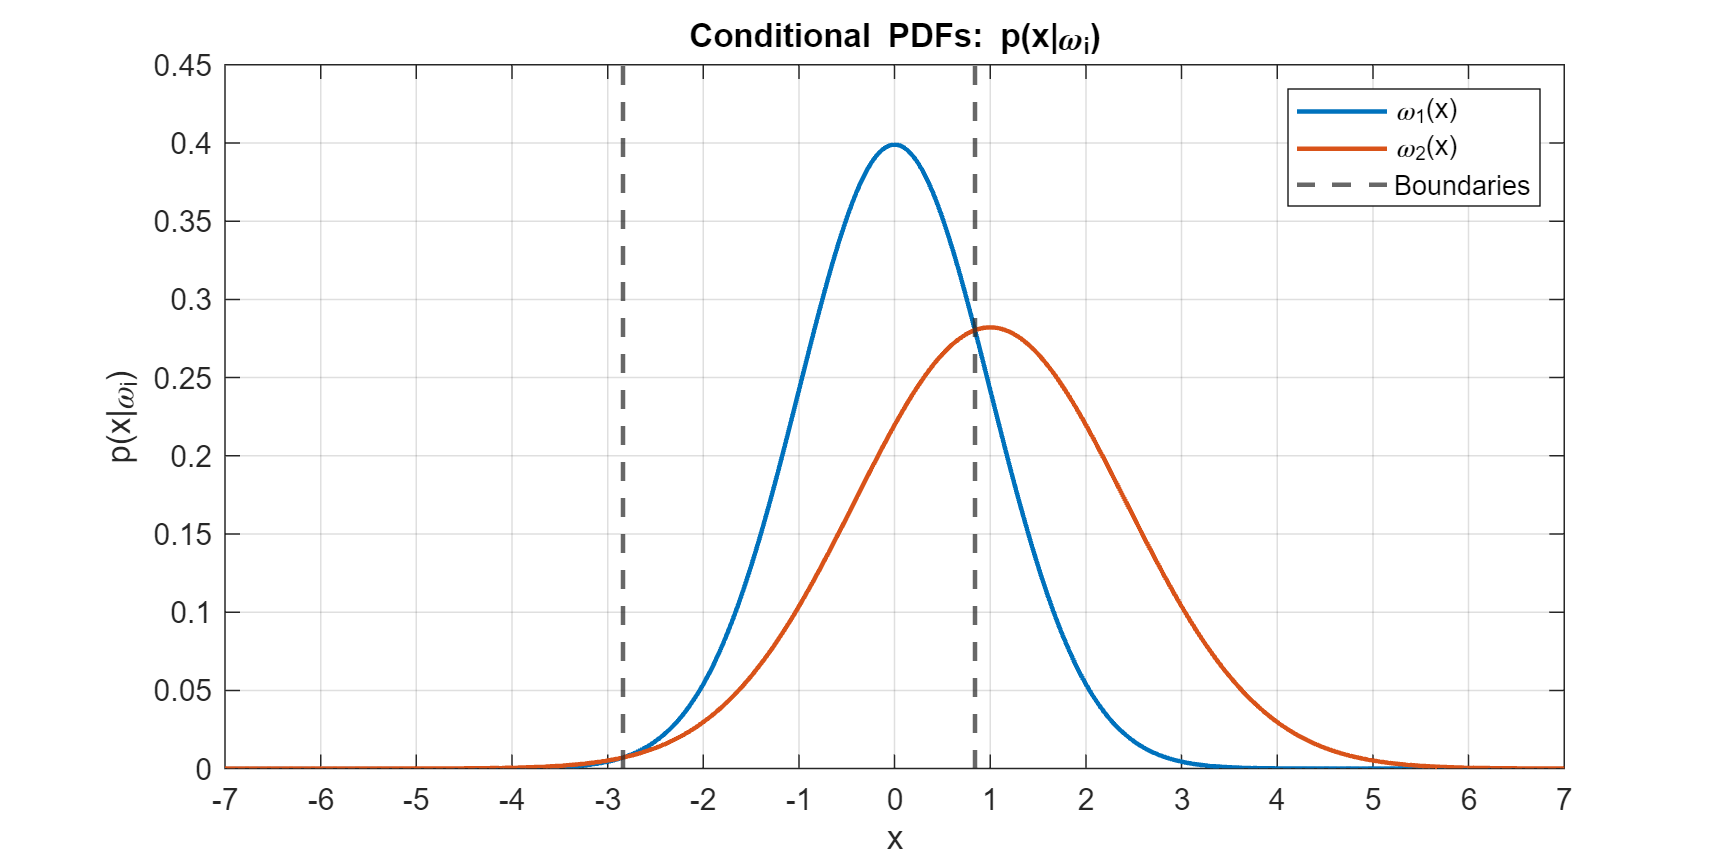

x1 = x_roots(1,:); 
x2 = x_roots(2,:); 
figure('Units','inches','Position',[0,0,8,4]);
plot(x,pxw1,'LineWidth',1.5), hold on, plot(x,pxw2,'LineWidth',1.5), grid on, xline(x1,'--','LineWidth',1.5), xline(x2,'--','LineWidth',1.5), hold off
xlabel('\it{x}'), ylabel('\it{p(x|\omega_i)}'), title('Conditional PDFs: p(x|\omega_i)')
xlim([-7 7]), xticks(-7:1:7), ylim([0 0.45]), legend('\it{\omega_1(x)}','\it{\omega_2(x)}','Boundaries')

Pw1 = 0.5;
Pw2 = 0.5;
px = pxw1.*Pw1 + pxw2.*Pw2;
pw1x = (pxw1.*Pw1)./px;
pw2x = (pxw2.*Pw2)./px;
pe = sum(min(pw1x,pw2x).*px) * .01

pe = 0.3272

pe = sum(min(pxw1.*Pw1,pxw2.*Pw2)) * .01

pe = 0.3272

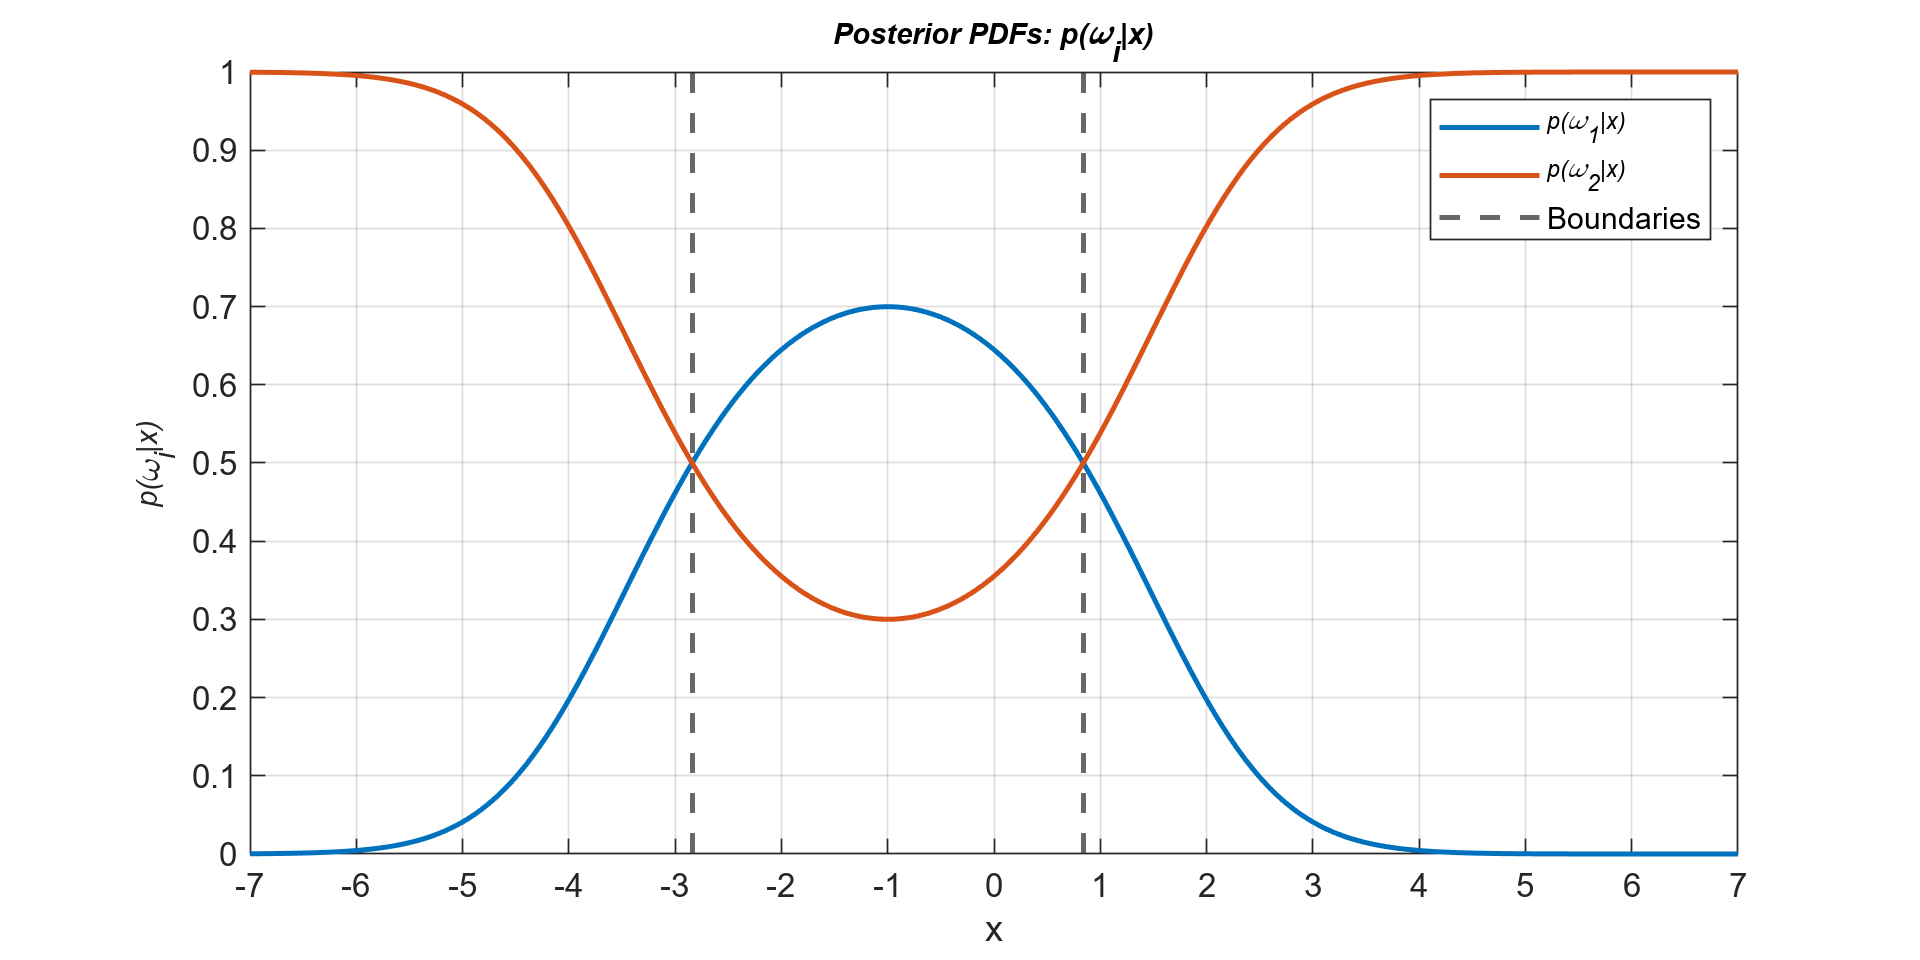

figure('Units','inches','Position',[0,0,8,4]);
plot(x,pw1x,'LineWidth',1.5), hold on, plot(x,pw2x,'LineWidth',1.5), grid on, xline(x1,'--','LineWidth',1.5), xline(x2,'--','LineWidth',1.5), hold off
xlabel('\it{x}'), ylabel('\it{p(\omega_i|x)}'), title('Posterior PDFs: \it{p(\omega_i|x)}')
xlim([-7 7]), xticks(-7:1:7), ylim([0 1]), legend('\it{p(\omega_1|x)}','\it{p(\omega_2|x)}', 'Boundaries')

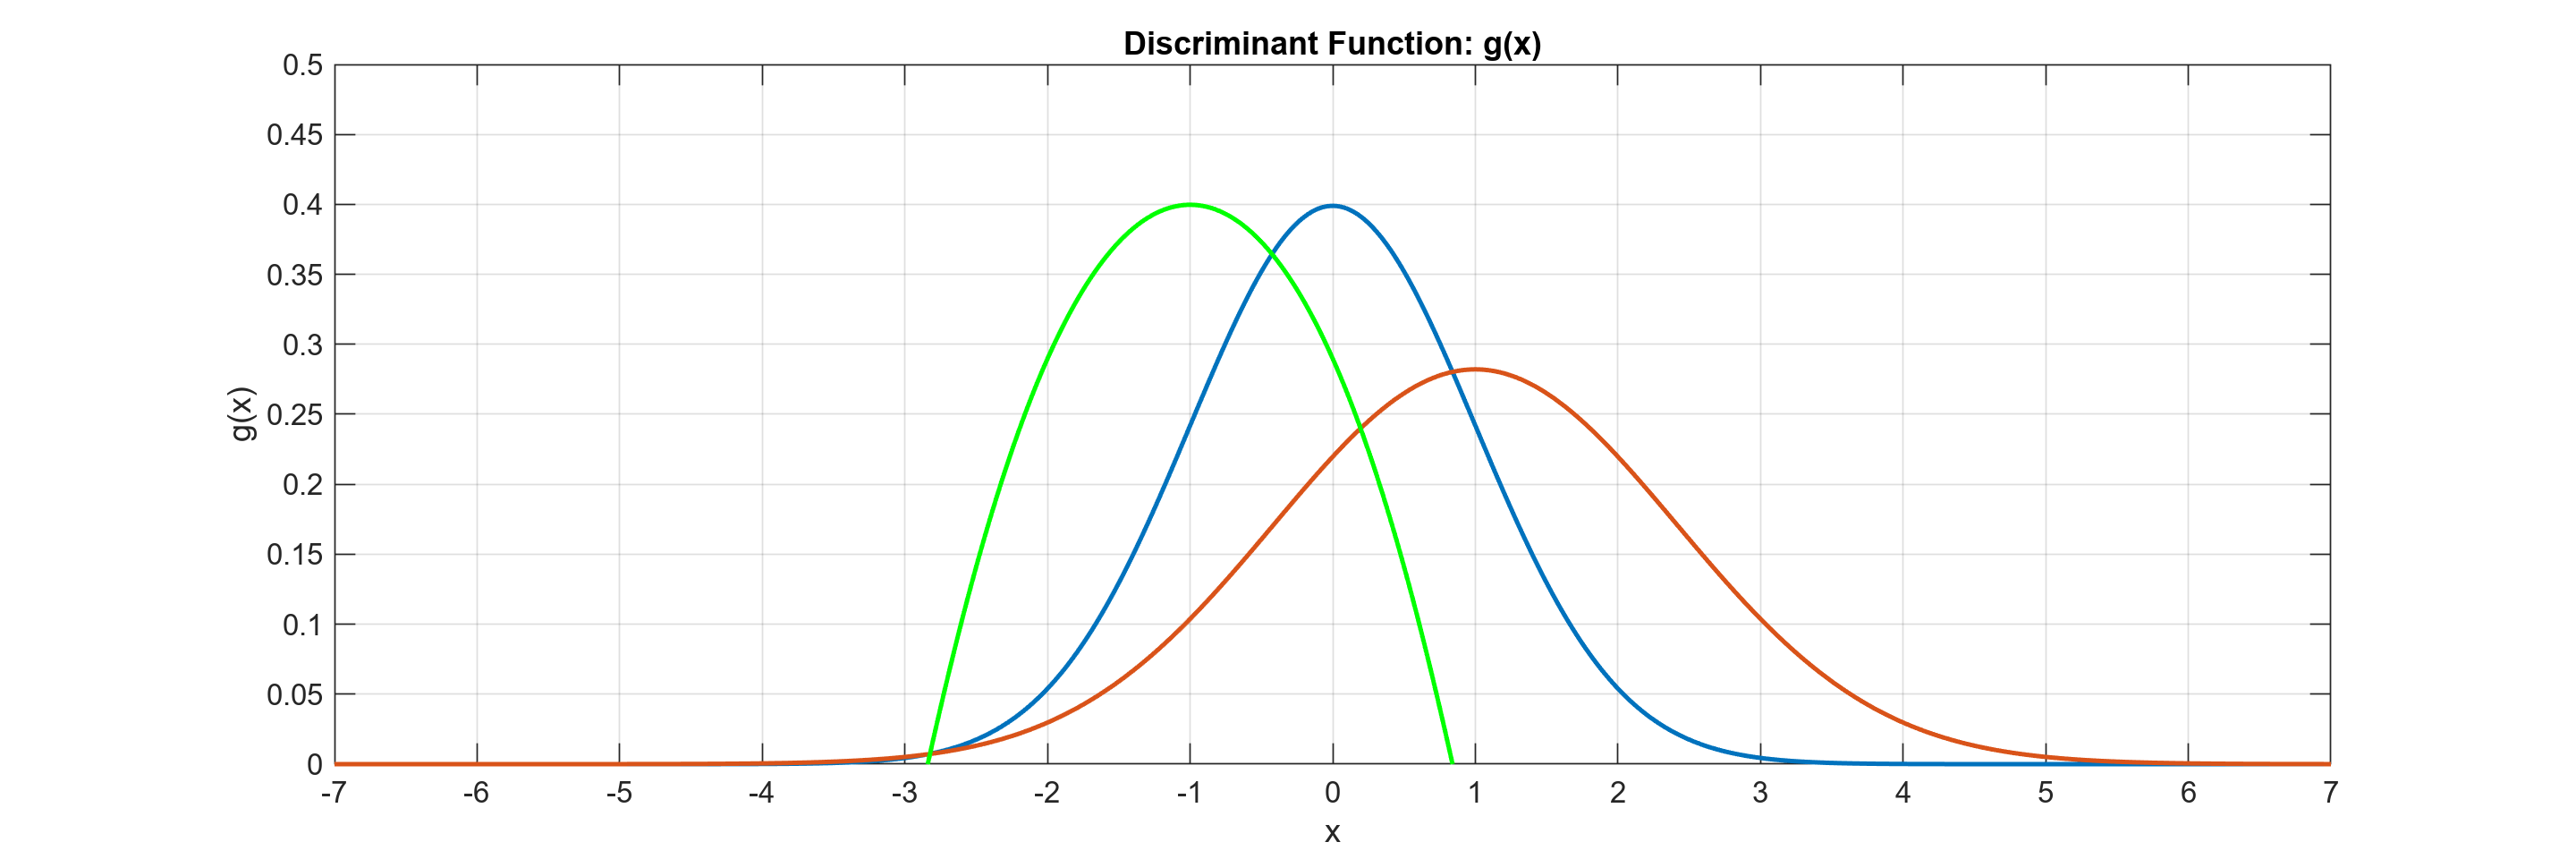

%gx = log(gx1./gx2);
gx = pw1x - pw2x;
figure('Units','inches','Position',[0,0,12,4]);
plot(x,pxw1,'LineWidth',1.5), hold on, plot(x,pxw2,'LineWidth',1.5), grid on
plot(x,gx,'g','LineWidth',1.5), grid on, hold off
xlabel('\it{x}'), ylabel('\it{g(x)}'), title('Discriminant Function: g(x)')
xlim([-7 7]), xticks(-7:1:7), ylim([0 0.5]), 

**(c.) **Estimate the Bayes error rate $p_e$.


$$P(error) = \int_{R_2} p(x|\omega_1)P(\omega_1)dx + \int_{R_1}p(x|\omega_2)P(\omega_2)dx$$


Filling in these terms and using the decision boundary expression for the intersection between these regions yields:


$$P(error) = P(\omega_1)\int_{-\infty}^{1/2} \frac{1}{\sqrt{2\pi\sigma_1^2}} e^{-\frac{(x-\mu_1)^2}{2\sigma_1^2}} dx + P(\omega_2)\int_{1/2}^{\infty} \frac{1}{\sqrt{2\pi\sigma_2^2}} e^{-\frac{(x-\mu_2)^2}{2\sigma_2^2}} dx$$



$$P(error) = P(\omega_1)\int_{-\infty}^{1/2} \frac{1}{\sqrt{2\pi}} e^{-\frac{x^2}{2}} dx + P(\omega_2)\int_{1/2}^{\infty} \frac{1}{\sqrt{4\pi}} e^{-\frac{(x-1)^2}{4}} dx$$


**(d.) **Comment on the case where $\mu =0,\;$and $\sigma^2 \gg 1\ldotp$ Describe a practical example of a pattern classification problem where such a situation might arise.  

A practical example could be in the case of Facial or Emotion Recognition. If the test data uses only one model's face, the means and variances would be close in value. However, if you were to use test data from multiple models' faces, the variety of facial structures, skin tone definition, lighting of the pictures, the image qualities, etc, could all contribute to a large variance for the test data set.